clear; clc;
load short_modem_rx.mat; % to decode the long phrase signal simply comment this line and uncomment the next line
% load long_modem_rx.mat;

% The received signal includes a bunch of samples from before the
% transmission started so we need discard the samples from before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset bynbg hn b the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission
y_t = y_t(1:msg_length*8*100);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Acoustic Modem Code

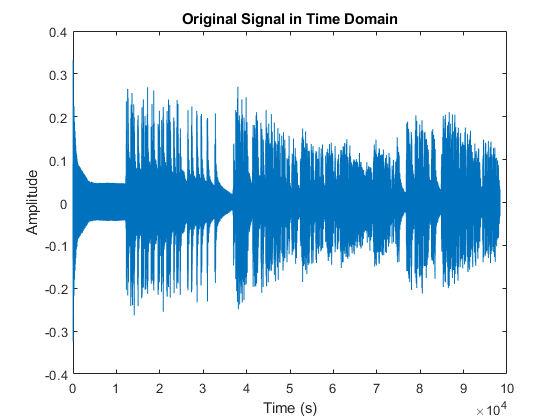

% Original Signal
Fs = 8192;
% time
plot(y_t);
title("Original Signal in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

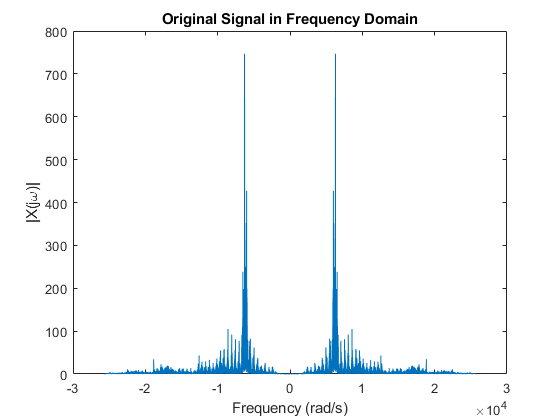

% freq
plot_ft_rad(y_t, Fs);
title("Original Signal in Frequency Domain");

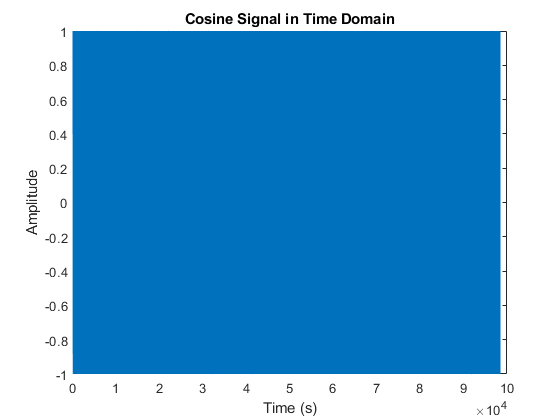

% Cosine Signal
f_c = 1000;
cos = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
% time
plot(cos);
title("Cosine Signal in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

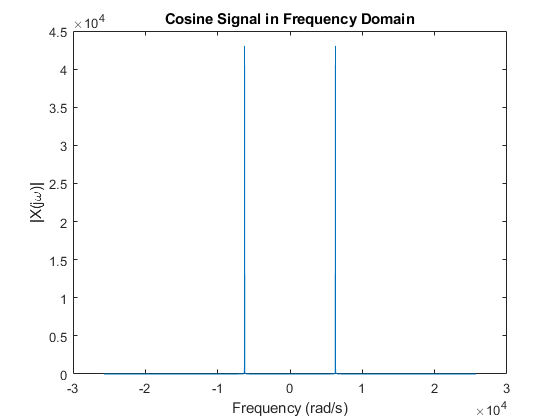

% freq
plot_ft_rad(cos, Fs);
title("Cosine Signal in Frequency Domain");

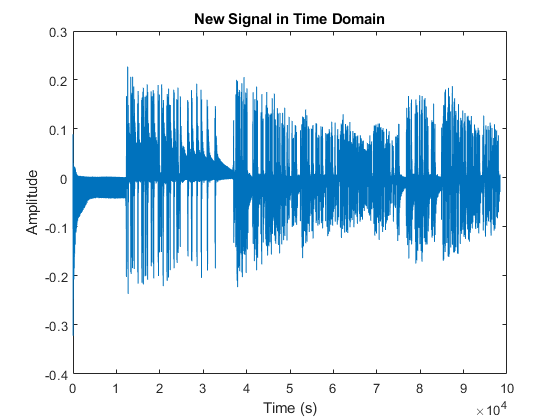

% Original Signal × Cosine Signal = New Signal
sig = y_t.*cos;
% time
plot(sig);
title("New Signal in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

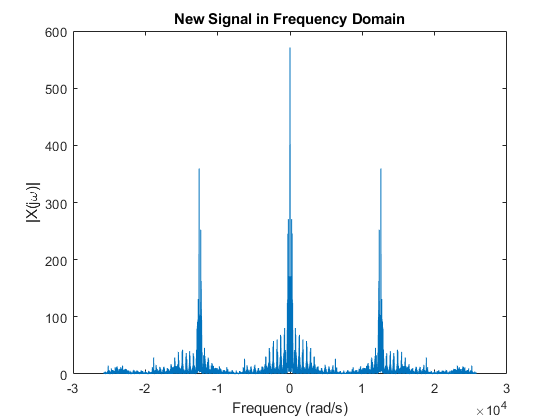

% freq
plot_ft_rad(sig, Fs);
title("New Signal in Frequency Domain");

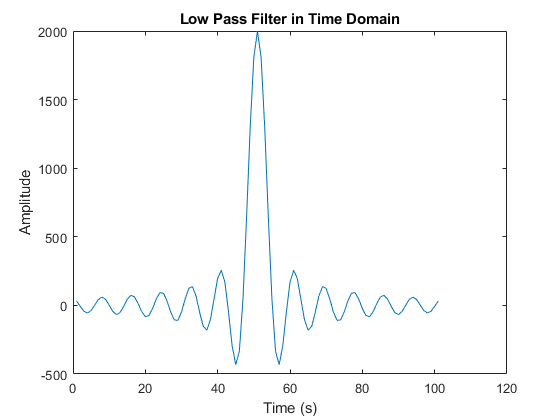

% Low Pass Filter
t = [-50:50]*1/Fs;
W = 2*pi*f_c;
h = W/pi*sinc(W/pi*t);
% time
plot(h);
title("Low Pass Filter in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

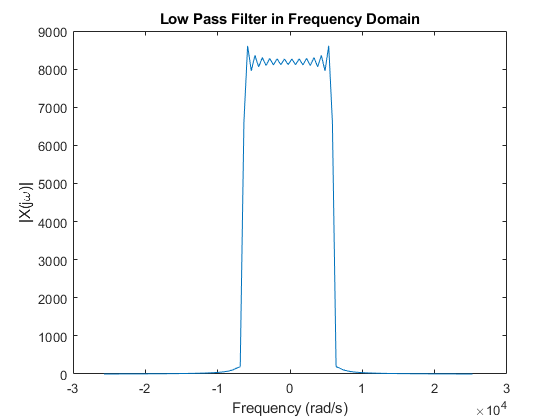

% freq
plot_ft_rad(h, Fs);
title("Low Pass Filter in Frequency Domain");

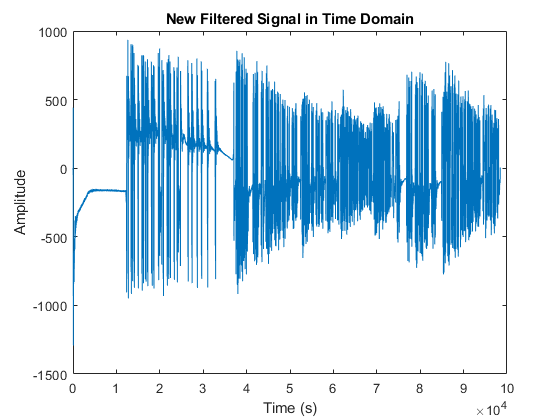

% New Signal ∗ Low Pass Filter = New Filtered Signal
sig_fl = conv(sig, h);
% time
plot(sig_fl);
title("New Filtered Signal in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

% Square Wave
sig_sq = square(sig_fl/500);

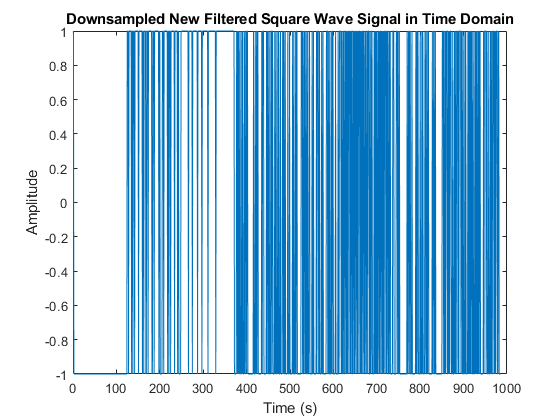

% Downsample
sig_dn = downsample(sig_sq, 100);
% time
plot(sig_dn);
title("Downsampled New Filtered Square Wave Signal in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

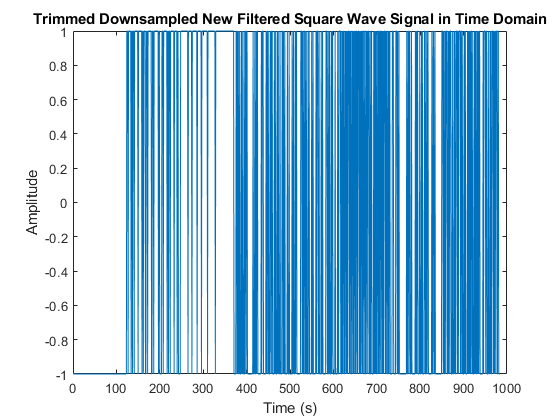

% Trimmed Signal
sig_tr = sig_dn(2:length(sig_dn));
plot(sig_tr);
title("Trimmed Downsampled New Filtered Square Wave Signal in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

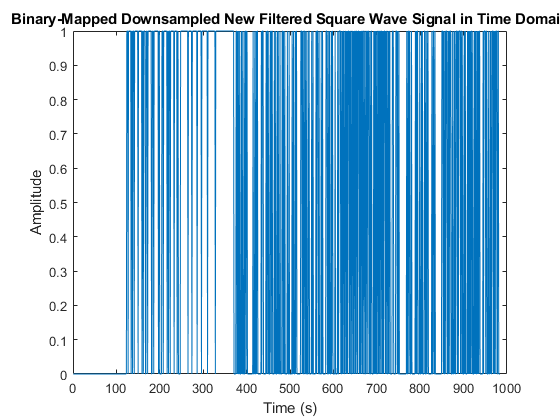

% Map Signal To Binary
for i = 1:length(sig_tr)
    if (sig_tr(i) == -1)
        sig_tr(i) = 0;
    else
        sig_tr(i) = 1;
    end
end
plot(sig_tr);
title("Binary-Mapped Downsampled New Filtered Square Wave Signal in Time Domain");
xlabel('Time (s)'); ylabel('Amplitude');

% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits
disp(BitsToString(sig_tr));

The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ...
